syms t w
eqn_t = (w-1)*377;
eqn_w = (1-1.2*sin(t)-(w-1))/10

$$eqn\_w = \frac{1}{5}-\frac{3\,\sin\left(t\right)}{25}-\frac{w}{10}$$

t_init = 0.3398;
w_init = 1;
tstore=[]


tstore =

     []



wstore=[]


wstore =

     []



ft=[]


ft =

     []



fw=[]


fw =

     []



time=[]


time =

     []



h=0.002;
for t_val = 0:h:0.1 % use a different variable name for the loop
    ft = [ft double(subs(eqn_t, [t, w], [t_init, w_init]))];
    fw = [fw double(subs(eqn_w, [t, w], [t_init, w_init]))];
    tval = double(t_init + h * subs(eqn_t, [t, w], [t_init, w_init]));
    wval = double(w_init + h * subs(eqn_w, [t, w], [t_init, w_init]));
    t_init = double(tval);
    w_init = double(wval);
    tstore=[tstore tval];
    wstore=[wstore wval];
    time=[time,t_val];
end
tstore

tstore =    0.339800000000000   0.339890486297190   0.340071440794310   0.340342829959833   0.340704604835621   0.341156701048693   0.341699038827111   0.342331523019973   0.343054043121520   0.343866473299350   0.344768672426740   0.345760484119079   0.346841736774396   0.348012243618003   0.349271802751225   0.350620197204241   0.352057194993010   0.353582549180292   0.355195997940762   0.356897264630201   0.358686057858771   0.360562071568364   0.362524985114022   0.364574463349414   0.366710156716373   0.368931701338481   0.371238719118692   0.373630817840978   0.376107591276006   0.378668619290810   0.381313467962462   0.384041689695719   0.386852823344643   0.389746394338155   0.392721914809529   0.395778883729791   0.398916787045007   0.402135097817437   0.405433276370529   0.408810770437728   0.412267015315072   0.415801434017544   0.419413437439151   0.423102424516684   0.426867782397146   0.430708886608785   0.434625101235709   0.438615779096029   0.442680261923489   0.446817

wstore

wstore =    1.000120008351711   1.000239992701751   1.000359932580270   1.000479807527570   1.000599597099565   1.000719280873233   1.000838838452072   1.000958249471548   1.001077493604549   1.001196550566831   1.001315400122465   1.001434022089280   1.001552396344306   1.001670502829207   1.001788321555724   1.001905832611099   1.002023016163504   1.002139852467467   1.002256321869282   1.002372404812427   1.002488081842962   1.002603333614931   1.002718140895745   1.002832484571564   1.002946345652664   1.003059705278794   1.003172544724518   1.003284845404547   1.003396588879050   1.003507756858954   1.003618331211217   1.003728293964090   1.003837627312350   1.003946313622512   1.004054335438013   1.004161675484372   1.004268316674310   1.004374242112854   1.004479435102386   1.004583879147671   1.004687557960839   1.004790455466321   1.004892555805747   1.004993843342788   1.005094302667957   1.005193918603348   1.005292676207320   1.005390560779126   1.005487557863473   1.005583

ft

ft =                    0   0.045243148594879   0.090477248560090   0.135694582761667   0.180887437893906   0.226048106536058   0.271168889209020   0.316242096431102   0.361260050773466   0.406215088914808   0.451099563695199   0.495905846169265   0.540626327658688   0.585253421803293   0.629779566611206   0.674197226508012   0.718498894384240   0.762677093641083   0.806724380234957   0.850633344719371   0.894396614284962   0.938006854796845   0.981456772829042   1.024739117695807   1.067846683479518   1.110772311054222   1.153508890105154   1.196049361143161   1.238386717514173   1.280514007401988   1.322424335825697   1.364110866628816   1.405566824461897   1.446785496755925   1.487760235687011   1.528484460131040   1.568951657608104   1.609155386214971   1.649089276545824   1.688747033599362   1.728122438672009   1.767209351236376   1.806001710803167   1.844493538766490   1.882678940231020   1.920552105819817   1.958107313462050   1.995338930159553   2.032241413730429   2.0688093145

fw

fw =    0.060004175855293   0.059992175020122   0.059969939259390   0.059937473650148   0.059894785997543   0.059841886834145   0.059778789419213   0.059705509737909   0.059622066500428   0.059528481141052   0.059424777817095   0.059310983407734   0.059187127512708   0.059053242450843   0.058909363258410   0.058755527687257   0.058591776202715   0.058418151981224   0.058234700907668   0.058041471572367   0.057838515267697   0.057625885984307   0.057403640406881   0.057171837909417   0.056930540549975   0.056679813064847   0.056419722862116   0.056150340014551   0.055871737251799   0.055583989951813   0.055287176131494   0.054981376436475   0.054666674130018   0.054343155080966   0.054010907750708   0.053670023179111   0.053320594969360   0.052962719271688   0.052596494765915   0.052222022642779   0.051839406584009   0.051448752741081   0.051050169712651   0.050643768520582   0.050229662584566   0.049807967695282   0.049378801986061   0.048942285903033   0.048498542173709   0.0480476957

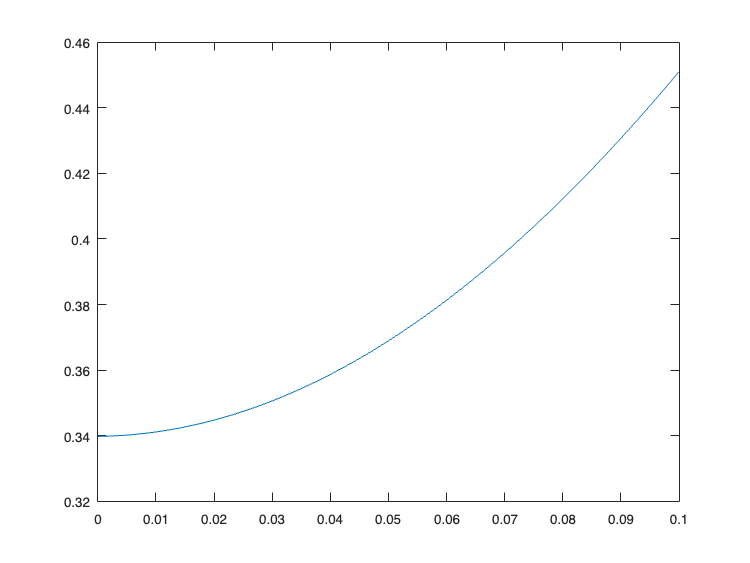

plot(time,tstore)

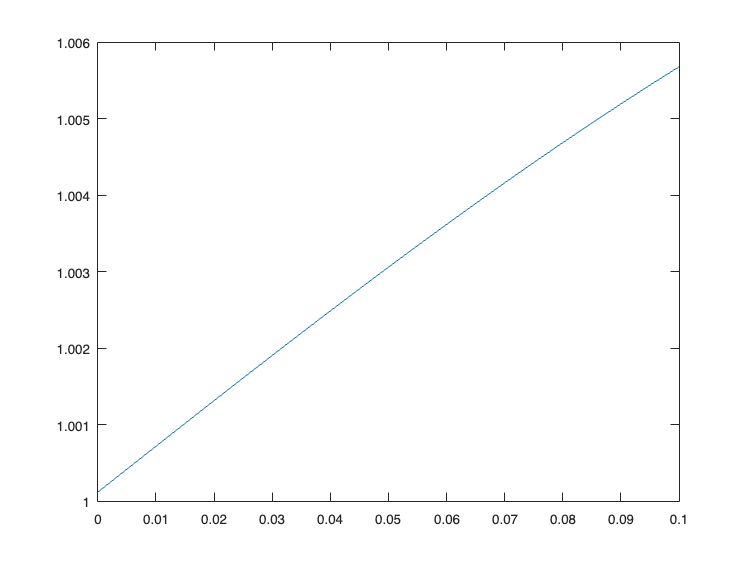

plot(time,wstore)


syms t w
eqn_t = w;
eqn_w = 9.425*(5.5-4.564*sin(t)-0.1*w)

$$eqn\_w = \frac{4147}{80}-\frac{430157\,\sin\left(t\right)}{10000}-\frac{377\,w}{400}$$

t_init = 0.50265;
w_init = 0;
tstore=[]


tstore =

     []



wstore=[]


wstore =

     []



ft=[]


ft =

     []



fw=[]


fw =

     []



time=[]


time =

     []



h=0.01;
for t_val = 0:h:0.2 % use a different variable name for the loop
    ft = [ft double(subs(eqn_t, [t, w], [t_init, w_init]))];
    fw = [fw double(subs(eqn_w, [t, w], [t_init, w_init]))];
    tval = double(t_init + h * subs(eqn_t, [t, w], [t_init, w_init]));
    wval = double(w_init + h * subs(eqn_w, [t, w], [t_init, w_init]));
    t_init = double(tval);
    w_init = double(wval);
    tstore=[tstore tval];
    wstore=[wstore wval];
    time=[time,t_val];
end
tstore

tstore =    0.502650000000000   0.505761471034325   0.511955087488477   0.521190081487778   0.533414521352877   0.548565690136038   0.566570562060264   0.587346374566575   0.610801293329738   0.636835166998047   0.665340367539448   0.696202710949645   0.729302451736897   0.764515343104742   0.801713753188362   0.840767826157368   0.881546675579646   0.923919596250069   0.967757279819622   1.012933019095173   1.059323885876894


wstore

wstore =    0.311147103432507   0.619361645415162   0.923499399930151   1.222443986509892   1.515116878316107   1.800487192422621   2.077581250631066   2.345491876316335   2.603387366830885   2.850520054140125   3.086234341019697   3.309974078725184   3.521289136784484   3.719841008361947   3.905407296900647   4.077884942227830   4.237292067042221   4.383768356955342   4.517573927555077   4.639086678172132   4.748798181539883


ft

ft =                    0   0.311147103432507   0.619361645415162   0.923499399930151   1.222443986509892   1.515116878316107   1.800487192422621   2.077581250631066   2.345491876316335   2.603387366830885   2.850520054140125   3.086234341019697   3.309974078725184   3.521289136784484   3.719841008361947   3.905407296900647   4.077884942227830   4.237292067042221   4.383768356955342   4.517573927555077   4.639086678172132


fw

fw =   31.114710343250675  30.821454198265535  30.413775451498914  29.894458657974059  29.267289180621493  28.537031410651444  27.709405820844463  26.791062568526989  25.789549051454948  24.713268730924014  23.571428687957134  22.373973770548766  21.131505805930011  19.855187157746318  18.556628853869935  17.247764532718307  15.940712481439084  14.647628991312111  13.380557059973512  12.151275061705507  10.971150336775185


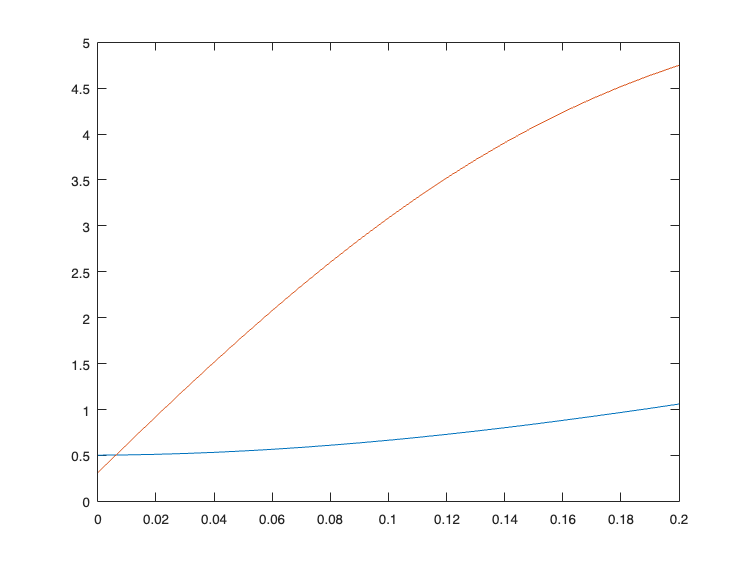

plot(time,tstore,time,wstore)

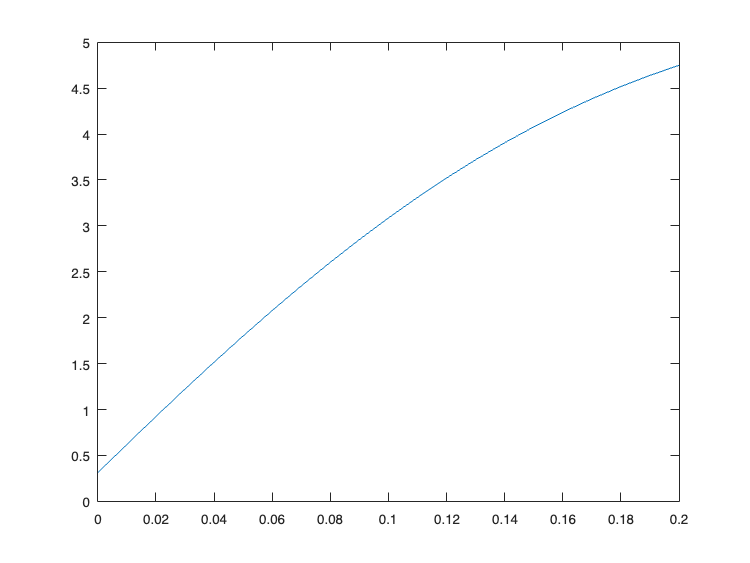

plot(time,wstore)